# Identificazione in frequenza in anello chiuso, con segnale eccitante sul setpoint

Motivazione:

- L'identificazione in anello aperto non consente di limitare l'andamento del sistema, causando possibili urti o il raggiungimento dei limiti del sistema

Obiettivi:

- analizzare le differenza fra la stima in anello aperto e anello chiuso

## Sistema simulato

uso un sistena motore-trasmissione elastica-carico

clear all;close all;clc;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi

s=tf('s');
dt=1e-3;
Jm=0.4;
Jl=0.6;

k=500;
h=3;


Carico il modello ottenuto dalla linearization block di simulink* (se cambiano i valori di *$J_m$*, *$J_l$*, *$k$*, *$h$* va ricalcolato)*

load modello_cli.mat
modello

modello =
 
  A = 
                 close_loop_i  close_loop_i  close_loop_i  close_loop_i
   close_loop_i             0            -1             0             0
   close_loop_i             0          -7.5           7.5         -1250
   close_loop_i             0             5            -5         833.3
   close_loop_i             0             1            -1             0
 
  B = 
                 Subsystem/1
   close_loop_i            0
   close_loop_i         -2.5
   close_loop_i            0
   close_loop_i            0
 
  C = 
                close_loop_i  close_loop_i  close_loop_i  close_loop_i
   Subsystem/1             0            -1             0             0
   Subsystem/2             1             0             0             0
 
  D = 
                Subsystem/1
   Subsystem/1            0
   Subsystem/2            0
 
Name: Linearization at model initial condition
Continuous-time state-space model.



il modello ha 

- due uscite: velocità e posizione; 

- un ingresso: la coppia. 

In questo esempio ci interessa stimare il legame coppia velocità. 

Uso il comando minreal per eliminare gli stati che non influisco nel legame coppia-velocità ( le posizioni assolute di motore e carico non ci interessano ma solo la loro posizione relativa)

Svilupperemo il controllore discreto con passo $dt=$1ms, per cui convertiamo in digitale.

P=c2d(minreal(modello(1)),dt);

1 state removed.


Nello schema simulink c'è la possibilità di aggiungere un carico, che simula le componenti gravitarie.

use_load=true;
if use_load
    tau_load=2;
else
    tau_load=0;
end

Per la legge di controllo che useremo dopo uso un modello approssimato che non considera la presenza della trasmissione elastica (vedi taratura_placement_motore.mlx)

J=Jl+Jm;
Papprox=c2d(1/(J*s),dt);

Se guardiamo la risposta in frequenza dei due modelli, vediamo che coincidono fino a prima dell'antirisonanza. 

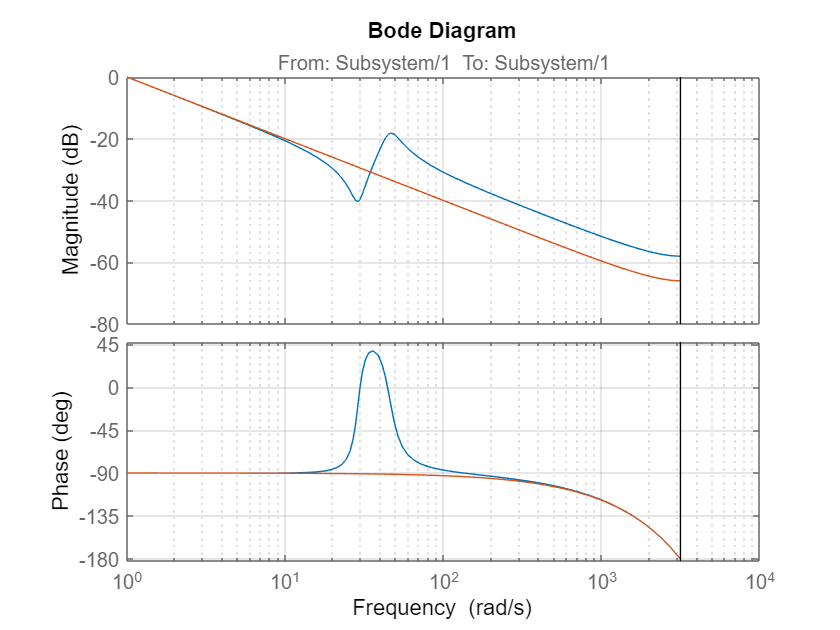

bode(P,Papprox)
grid on

legend('Sistema elastico','sistema rigido approssimato')

## Identificazione close-loop / open-loop

Il segnale eccitante può essere fornito in ingresso al sistema controllato in open-loop, dove non avremmo nessun controllo sul sistema che potrebbe derivare dal punto di equilibrio desiderato.

E' possibile eccitare il sistema anche in close-loop, inserendo il segnale eccitante attraverso il setpoint o sommandolo all'uscita del controllore.

Consideriamo il primo caso. 

omegaF=15; % per la taratura, scelgo di piazzare i poli in 15 rad/s, ma ogni altra taratura che non causa instabilità andrebbe bene
Kp=2*omegaF*J;
Ki=omegaF^2*J;
C=Kp+Ki/s;
C=c2d(C,dt);


L=P*C;
F=L/(1+L);
F_y_r=L/(1+L);
F_u_r=C/(1+L);

Plotto le funzioni di trasferimento:

- fra coppia $U(s)$ e velocità del sistema $Y(s)$ in anello aperto, $\frac{Y(s)}{U(s)}=P(s)$

- fra segnale eccitante $R(s)$ e velocità del sistema $Y(s)$.  $\frac{Y(s)}{R(s)}=\frac{PC}{1+PC}$

- fra segnale eccitante $R(s)$ e coppia del sistema $U(s)$.  $\frac{U(s)}{R(s)}=\frac{C}{1+PC}$

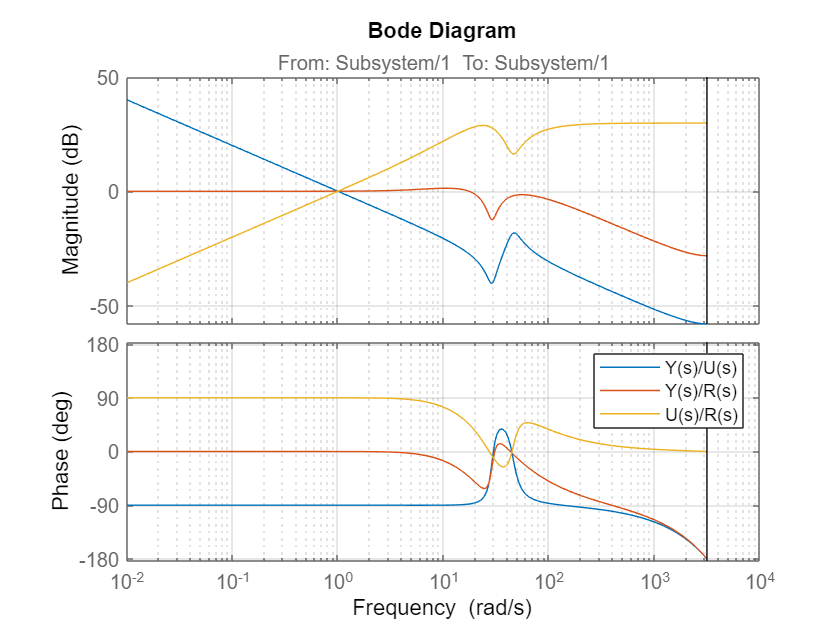

figure
bode(P,F_y_r,F_u_r)
grid on
legend('Y(s)/U(s)','Y(s)/R(s)','U(s)/R(s)')
xlim([1e-2 1e4])

Quando il controllo è attivo, si può vedere come il controllore agisca per inseguire il segnale eccitante. Questa compensazione è tanto più buona tanto più è alto il guadagno del controllore a quella frequenza.

Infatti se $C\rightarrow\infty$ le funziona di trasferimento tendono a 

$C\rightarrow\infty$,        $\frac{U(s)}{R(s)}=\frac{C}{1+PC}\rightarrow \frac{1}{P}$,         $\frac{Y(s)}{R(s)}=\frac{PC}{1+PC}\rightarrow 1$    

Essendo il controllore dotato di integratore, compenserà molto bene le basse frequenze.

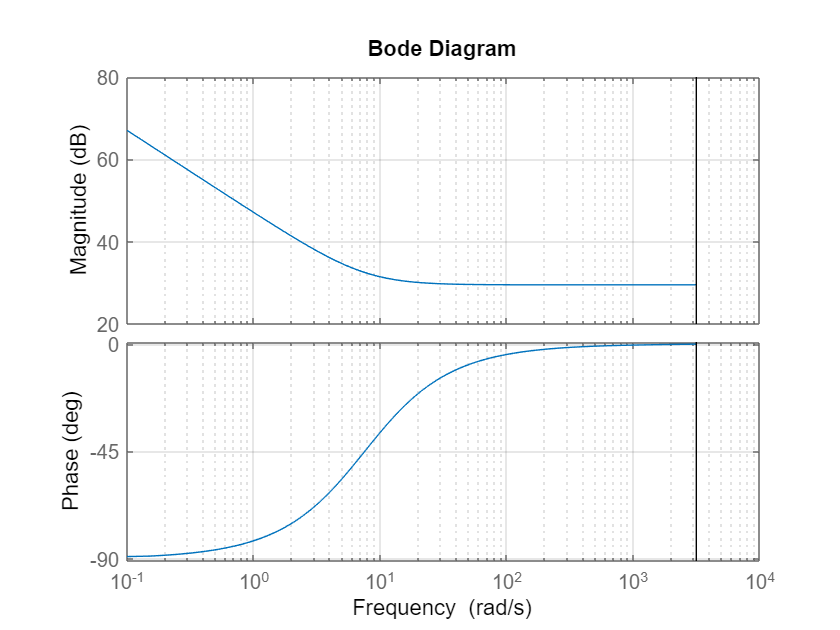

figure
bode(C)
grid on

Nelle frequenze in cui il controllore compensa il segnale eccitante, avremo una stima in frequenza peggiore. **Nell'identificazione conviene usare un controllore non troppo aggressivo, in modo che non compensi "*****troppo"***** i disturbi.**

## Progetto del segnale eccitante

uso un chirp fra $\omega_0$ e $\omega_1$ distribuito logaritmicamente, con un esperimento di durata $T_{end}$, il riferimento lo lascio a 0. E' possibile aggiungere la portate, o utilizzare un altro segnale.

Tend=30;
t=(0:dt:Tend)';

w0=0.5;
w1=300;


uE=zeros(length(t),1);
r=0.05*chirp(t,w0/2/pi,Tend,w1/2/pi,'logarithmic',90); % parto con una fase di 90 gradi (come un seno), scelgo 0.05 per avere un'ampiezza simile al caso "close_loop_ident_coppia.mlx"

Posso attivare o disattivare il rumore nella simulazione

use_noise=true;
if (use_noise)
    n_std=0.01;
else
    n_std=0;
end
n=n_std*randn(length(t),1);

eseguo la simulazione

simOut=sim('close_loop_identification.slx',[0 Tend],'',[t r uE n]);

Simulink ha un solutore a passo variabile, ricampiono le uscite con il tempo equispaziato $t$

y_timeseries=simOut.yout{1}.Values.resample(t);
y=y_timeseries.Data;

u_timeseries=simOut.yout{2}.Values.resample(t);
u=u_timeseries.Data;

uC_timeseries=simOut.yout{3}.Values.resample(t);
uC=uC_timeseries.Data;

a_timeseries=simOut.yout{4}.Values.resample(t);
a=a_timeseries.Data;


Grafico l'andamento dell'uscita e dell'azione di controllo

layout=tiledlayout(2,1);

Il primo grafico è l'andamento dell'uscita.  **Nota**: il transitorio iniziale influisce sulla bontà della stima, il sistema in anello chiuso avrà un transitorio minore

nexttile
plot(t,y,t,r)
xlabel('t')
ylabel('y')
grid on
legend('y','r')

Il secondo grafico è l'andamento dell'azione di controllo, si può vedere come nel primo tratto è quasi zero, perchè $1/P$ è quasi zero a basse frequenze.

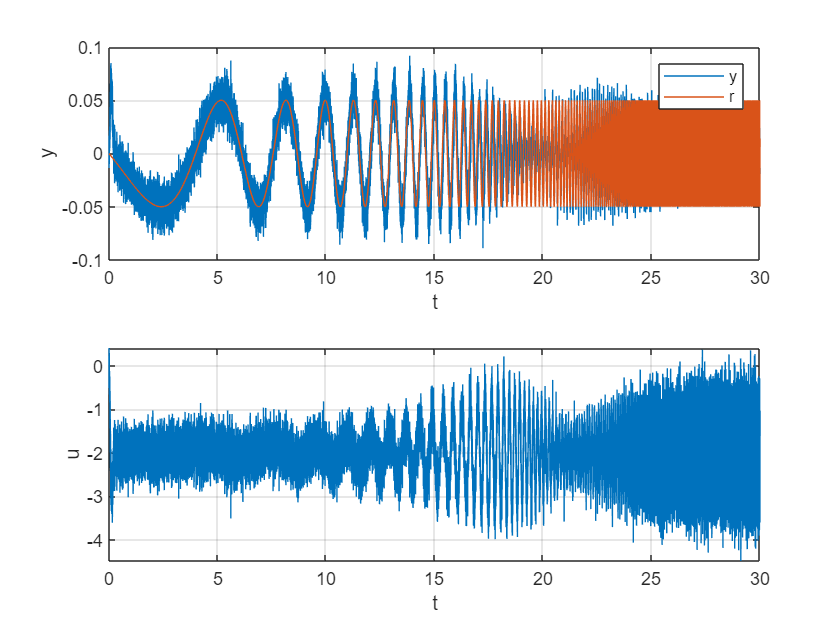

nexttile
plot(t,u)
xlabel('t')
ylabel('u')
grid on

## Calcolo della risposta in frequenza sperimentale

costruisco i dati di identificazione

identification=iddata(y,u,dt);

calcolo la risposta in frequenza

identification_fr=spafdr(identification);

Disegno il diagramma di Bode del sistema

figure
bodeplot(P);
hold on
grid on

e plotto il diagramma di bode sperimentale con intervallo di confidenza $\pm 3$ volte la deviazione standard

bode_line=bodeplot(identification_fr);
showConfidence(bode_line,3)

Le linee verticali tratteggiate rappresentano $\omega_0$ e $\omega_1$, cioè il range di frequenza in cui ho inniettato segnale eccitante.

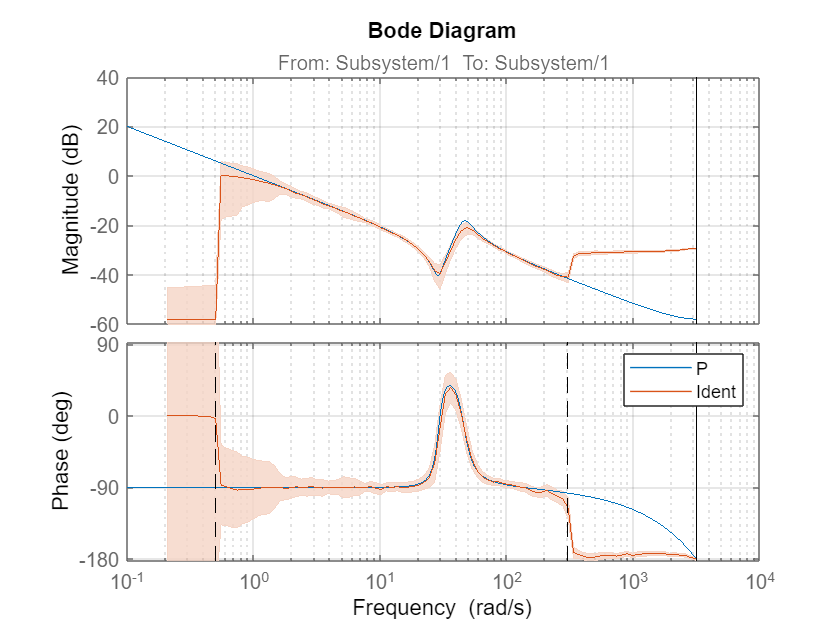

plot([w0 w0],ylim,'--k')
plot([w1 w1],ylim,'--k')

legend('P','Ident')

## Andamento della posizione

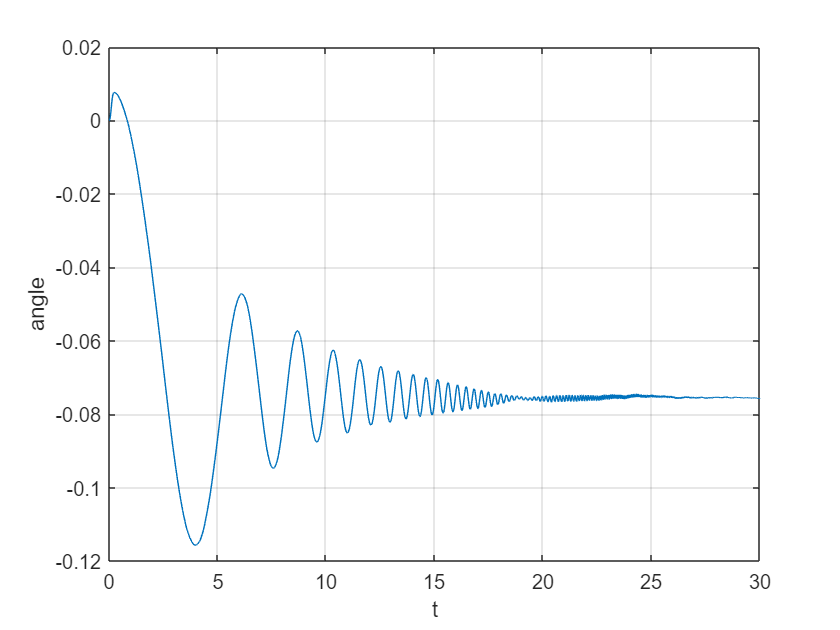

figure
plot(t,a)
grid on
xlabel('t')
ylabel('angle')